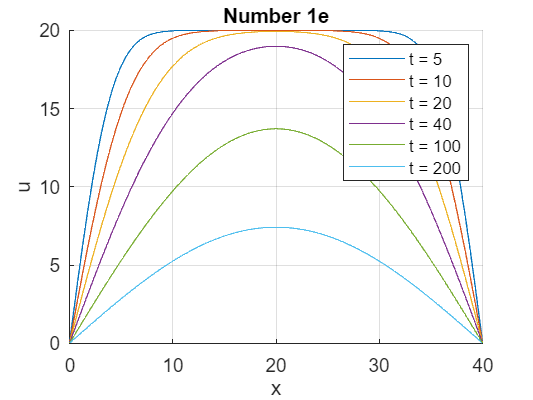

x = linspace(0,40,500);             % values of x
t = [5, 10, 20, 40, 100, 200];      % values of t

lgnd = [];                          % for storing legend

% appending legend
for i = 1:6
    lgnd = [lgnd, sprintf("t = %d", t(i))];
end

hold on
grid on
title("Number 1e")                  % make the title

for i = 1:6
    un = u(x, t(i));                % get u(x) for each t
    plot(x, un);                    % plotting the u(x) vs. x
end

legend(lgnd)                        % make the legends

xlabel("x")                         % give x-axis label
ylabel("u")                         % give y-axis label
hold off

Nomor 2b

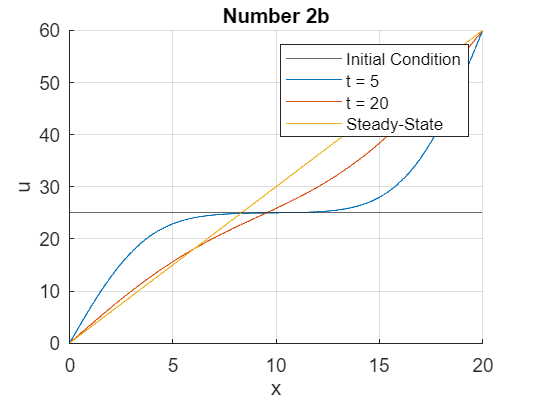

clf

x = linspace(0,20,500);           % values of x
t = [5, 20];                      % values of representative t

lgnd = ["Initial Condition"];     % for storing legends

% appending legend
for i = 1:length(t)
    lgnd = [lgnd, sprintf("t = %d", t(i))];
end
lgnd = [lgnd, "Steady-State"];

hold on
grid on
title("Number 2b")                  % make the title

yline(25);                          % plot IC

for i = 1:length(t)
    un = u2b(x, t(i));              % get u(x) for each representative t
    plot(x, un);                    % plotting the u(x) vs. x
end

plot(x, u2bss(x));                  % plot steady state

legend(lgnd)                        % make the legends

xlabel("x")                         % give x-axis label
ylabel("u")                         % give y-axis label

Nomor 3b

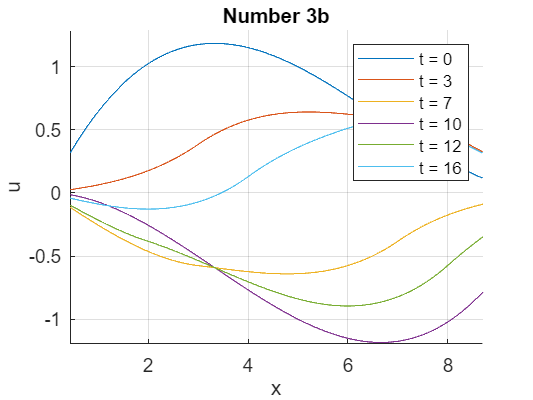

clf

x = linspace(0,10,500);             % values of x
t = [0, 3, 7, 10, 12, 16];            % values of t

lgnd = [];                          % for storing legend

% appending legend
for i = 1:6
    lgnd = [lgnd, sprintf("t = %g", t(i))];
end

hold on
grid on
title("Number 3b")                  % make the title

for i = 1:6
    un = u3b(x, t(i));                % get u(x) for each t
    plot(x, un);                    % plotting the u(x) vs. x
end

legend(lgnd)                        % make the legends

xlabel("x")                         % give x-axis label
ylabel("u")                         % give y-axis label

No 3c

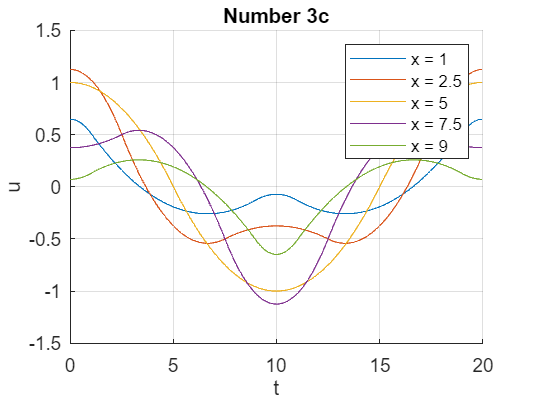

clf

x = [1, 2.5, 5, 7.5, 9];             % values of x
t = linspace(0,20,500);            % values of t

lgnd = [];                          % for storing legend

% appending legend
for i = 1:5
    lgnd = [lgnd, sprintf("x = %g", x(i))];
end

hold on
grid on
title("Number 3c")                  % make the title

for i = 1:5
    un = u3b(x(i), t);                % get u(x) for each t
    plot(t, un);                    % plotting the u(x) vs. x
end

legend(lgnd)                        % make the legends

xlabel("t")                         % give x-axis label
ylabel("u")                         % give y-axis label

No 3d

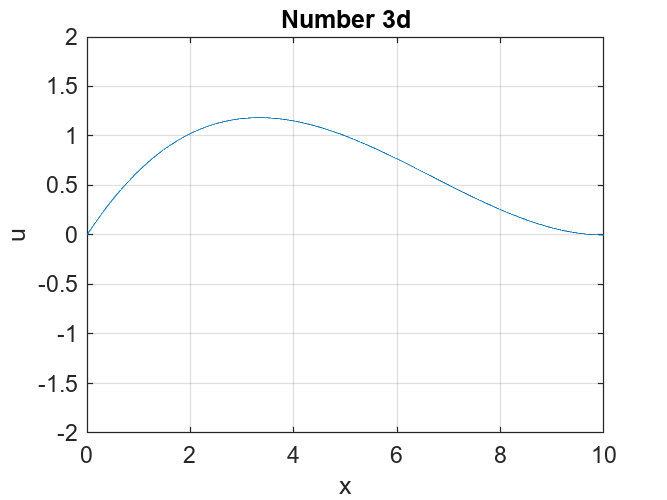

clf

x = linspace(0,10,500);             % values of x
t = 0:0.1:20;            % values of t

for T=t
    plot(x, u3b(x, T));
    grid on

    xlim([0 10]);
    ylim([-2 2]);

    title("Number 3d")

    xlabel("x")                         % give x-axis label
    ylabel("u")                         % give y-axis label

    pause(0.1);                     
end

function temp = u(x, t)
    temp = 0;
    
    for m = 1:1000
        temp = temp + 1 / (2 * m - 1) * exp(-t * ((2 * m - 1) * pi / 40)^2) * sin((2 * m - 1) * pi * x / 40);
    end
    
    temp = temp * 80 / pi;
end

No 2b

function temp = u2b(x, t)
    steady = 3 * x;
    
    sum = 0;
    
    for n = 1:10000
        sum = sum + 10 / (n * pi) * (5 + 7 * (-1)^(n)) * exp(-(0.8418) * (n * pi /20)^2 * t) * sin(n * pi * x/20);
    end
    
    temp = sum + steady;
end

function temp = u2bss(x)
    temp = 3 * x;
end

No 3b

function temp = u3b(x, t)
    temp = 0;
    
    for n = 1:1000
        temp = temp + 1 / n^3 * (2 + (-1)^n) * sin(n * pi * x/10) * cos(n * pi * t/10);
    end
    
    temp = temp * 32 / pi^3;
end